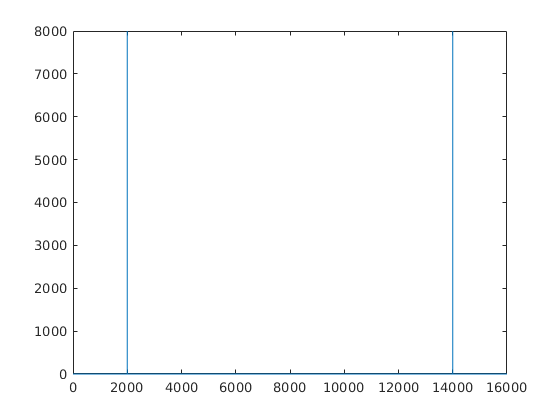

% Task 3
   Fs = 16000;                  
   f = 2000;                
   n = [1:16000];
   x = sin(2*pi*n*f/Fs);
   y = fft(x);
   z = abs(y);
   plot(n,z);

% Task 4
clear all
x = [1 2 3 4]';

dft_result = dft(x)

dft_result =   10.0000 + 0.0000i
  -2.0000 + 2.0000i
  -2.0000 - 0.0000i
  -2.0000 - 2.0000i


fft_result = fft(x)

fft_result =   10.0000 + 0.0000i
  -2.0000 + 2.0000i
  -2.0000 + 0.0000i
  -2.0000 - 2.0000i


% Task 5 - a
clear all
x=rand(1024,1);

tic(); % Starts a stopwatch timer
dft_result=dft(x) % DFT computation

dft_result = 	1.0e+02 *

   5.1050 + 0.0000i
   0.0533 + 0.0152i
  -0.0257 + 0.1080i
   0.0369 - 0.1070i
   0.0755 - 0.0565i
   0.0058 + 0.0684i
  -0.0762 + 0.0123i
   0.0264 - 0.0034i
   0.1814 - 0.0826i
  -0.0325 + 0.0883i


elapsed_time_dft=toc(); % Reads the elapsed time from the timer

tic(); % Starts a stopwatch timer
fft_result=fft(x)  % DFT computation

fft_result = 	1.0e+02 *

   5.1050 + 0.0000i
   0.0533 + 0.0152i
  -0.0257 + 0.1080i
   0.0369 - 0.1070i
   0.0755 - 0.0565i
   0.0058 + 0.0684i
  -0.0762 + 0.0123i
   0.0264 - 0.0034i
   0.1814 - 0.0826i
  -0.0325 + 0.0883i


elapsed_time_fft=toc(); % Reads the elapsed time from the timer

disp(["Time Taken by DFT", elapsed_time_dft])

    "Time Taken by DFT"    "0.59134"



disp(["Time Taken by FFT", elapsed_time_fft])

    "Time Taken by FFT"    "0.12141"



% Task 5 - b
clear all
sum_dft = 0;
sum_fft = 0;
for i = 1:100
    x=rand(1024,1);
    
    tic(); % Starts a stopwatch timer
    dft_result=dft(x); % DFT computation
    elapsed_time_dft=toc(); % Reads the elapsed time from the timer
    sum_dft = sum_dft + elapsed_time_dft;
    
    tic(); % Starts a stopwatch timer
    fft_result=fft(x);  % DFT computation
    elapsed_time_fft=toc(); % Reads the elapsed time from the timer
    sum_fft = sum_fft + elapsed_time_fft;
end
disp(["Estimate time by DFT", sum_dft/100])

    "Estimate time by DFT"    "0.061835"



disp(["Estimate time by FFT", sum_fft/100])

    "Estimate time by FFT"    "6.046e-05"



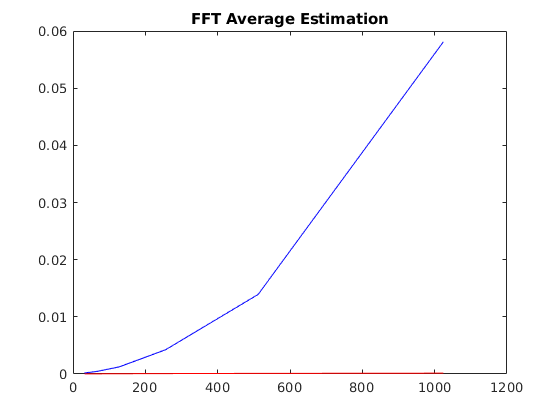

% Task 5 - c
clear all
N = [32, 64, 128, 256, 512, 1024];
estimate_dft = [];
estimate_fft = [];
sum_dft = 0;
sum_fft = 0;
k = 1;
for N1=N(1:length(N))
    for i = 1:100
        x=rand(N1,1);
        
        tic(); % Starts a stopwatch timer
        dft_result=dft(x); % DFT computation
        elapsed_time_dft=toc(); % Reads the elapsed time from the timer
        sum_dft = sum_dft + elapsed_time_dft;
        
        tic(); % Starts a stopwatch timer
        fft_result=fft(x);  % DFT computation
        elapsed_time_fft=toc(); % Reads the elapsed time from the timer
        sum_fft = sum_fft + elapsed_time_fft;
    end
    estimate_dft(k) = sum_dft/100;
    estimate_fft(k) = sum_fft/100;
    k= k+1;
end

% Task 5 - d

plot(N,estimate_dft, 'b')
title("DFT Average Estimation")
hold on
plot(N,estimate_fft, 'r')
title("FFT Average Estimation")
hold off

function dft_result = dft(x)
    N = length(x);
    F=exp(-2*pi*1i*(0:N-1)'*(0:N-1)/N);
    dft_result = F*x;
end